clc;
clear;
clf;

data = 'free_space';
contact = 'no_contact';
test_folder = 'trial_5';
rnn = 'lstm';
% network = '_seal_pred_filtered_torque_glove_1_15.csv';
network = '_seal_pred_filtered_torque_colon_3_27.csv';
% network = '_seal_pred_filtered_torque_si_3_15.csv';

%loss = 0;
loss = [0,0,0,0];

%for file = 0:3
file = 0;
exp = ['exp',num2str(file)];

arm1 = 'psm1_mary';
arm2 = 'psm2_fen';

      joint_path_1 = ['../../dvrk_colon_3_26_24/colon_exp_mar_26/', test_folder, '/', arm1, '/', data, '/joints/'];
      jacobian_path_1 = ['../../dvrk_colon_3_26_24/colon_exp_mar_26/',  test_folder, '/', arm1, '/', data, '/jacobian/'];
      torque_path_1 = ['../../dvrk_colon_3_26_24/colon_exp_mar_26/', test_folder, '/', arm1, '/', data, '/', 'lstm', network];

      joint_path_2 = ['../../dvrk_colon_3_26_24/colon_exp_mar_26/', test_folder, '/', arm2, '/', data, '/joints/'];
      jacobian_path_2 = ['../../dvrk_colon_3_26_24/colon_exp_mar_26/',  test_folder, '/', arm2, '/', data, '/jacobian/'];
      torque_path_2 = ['../../dvrk_colon_3_26_24/colon_exp_mar_26/', test_folder, '/', arm2, '/', data, '/', 'lstm', network];

%       joint_path_1 = ['../../glove_jan_10/', test_folder, '/', arm1, '/', data, '/joints/'];
%       jacobian_path_1 = ['../../glove_jan_10/',  test_folder, '/', arm1, '/', data, '/jacobian/'];
%       torque_path_1 = ['../../glove_jan_10/', test_folder, '/', arm1, '/', data, '/', 'lstm', network];
% 
%       joint_path_2 = ['../../glove_jan_10/', test_folder, '/', arm2, '/', data, '/joints/'];
%       jacobian_path_2 = ['../../glove_jan_10/',  test_folder, '/', arm2, '/', data, '/jacobian/'];
%       torque_path_2 = ['../../glove_jan_10/', test_folder, '/', arm2, '/', data, '/', 'lstm', network];

joint_data_1 = readmatrix([joint_path_1, 'interpolated_all_joints.csv']);
jacobian_data_1 = readmatrix([jacobian_path_1, 'interpolated_all_jacobian.csv']);
torque_data_1 = readmatrix(torque_path_1);

joint_data_2 = readmatrix([joint_path_2, 'interpolated_all_joints.csv']);
jacobian_data_2 = readmatrix([jacobian_path_2, 'interpolated_all_jacobian.csv']);
torque_data_2 = readmatrix(torque_path_2);


real_force_path = ['../../dvrk_colon_3_26_24/colon_exp_mar_26/', test_folder, '/', arm1, '/', 'sensor/'];
% real_force_path = ['../../glove_jan_10/', test_folder, '/' , arm1, '/', 'sensor/'];
real_force_data = readmatrix([real_force_path, 'interpolated_all_sensor.csv']);
real_force = real_force_data(1:length(torque_data_1),2:7);

jacobian_1 = jacobian_data_1(:, 2:37).';
jacobian_1 = reshape(jacobian_1,[6,6,length(jacobian_1)]);
jacobian_1 = permute(jacobian_1, [2 1 3]);

jacobian_2 = jacobian_data_2(:, 2:37).';
jacobian_2 = reshape(jacobian_2,[6,6,length(jacobian_2)]);
jacobian_2 = permute(jacobian_2, [2 1 3]);

joint_data_2(:,:,1);


fs_pred_torque_1 = torque_data_1(:,2:7).';
% fs_pred_torque = fs_pred_torque(:, 1:length(fs_pred_torque)/2);
measured_torque_1 = joint_data_1(1:length(fs_pred_torque_1),14:19).';
jacobian_1 = jacobian_1(:,:,1:length(fs_pred_torque_1));

fs_diff_1 = measured_torque_1 - fs_pred_torque_1;
fs_force_1 = zeros(6,length(fs_pred_torque_1));
angle1 = -1/4*pi;
rotation1 = [cos(angle1) -sin(angle1) 0; sin(angle1) cos(angle1) 0; 0 0 1]

rotation1 =     0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000



for i = 1:length(fs_pred_torque_1)
    fs_force_1(:,i) = inv(jacobian_1(:,:,i).') * (fs_diff_1(:,i));
    fs_force_1(1:3, i) = rotation1 * fs_force_1(1:3, i);
end

fs_force_1 = fs_force_1.';



fs_pred_torque_2 = torque_data_2(:,2:7).';
% fs_pred_torque = fs_pred_torque(:, 1:length(fs_pred_torque)/2);
measured_torque_2 = joint_data_2(1:length(fs_pred_torque_2),14:19).';
jacobian_2 = jacobian_2(:,:,1:length(fs_pred_torque_2));

fs_diff_2 = measured_torque_2 - fs_pred_torque_2;
fs_force_2 = zeros(6,length(fs_pred_torque_2));
angle2 = -3*pi/4;
rotation2 = [cos(angle2) -sin(angle2) 0; sin(angle2) cos(angle2) 0; 0 0 1]

rotation2 =    -0.7071    0.7071         0
   -0.7071   -0.7071         0
         0         0    1.0000


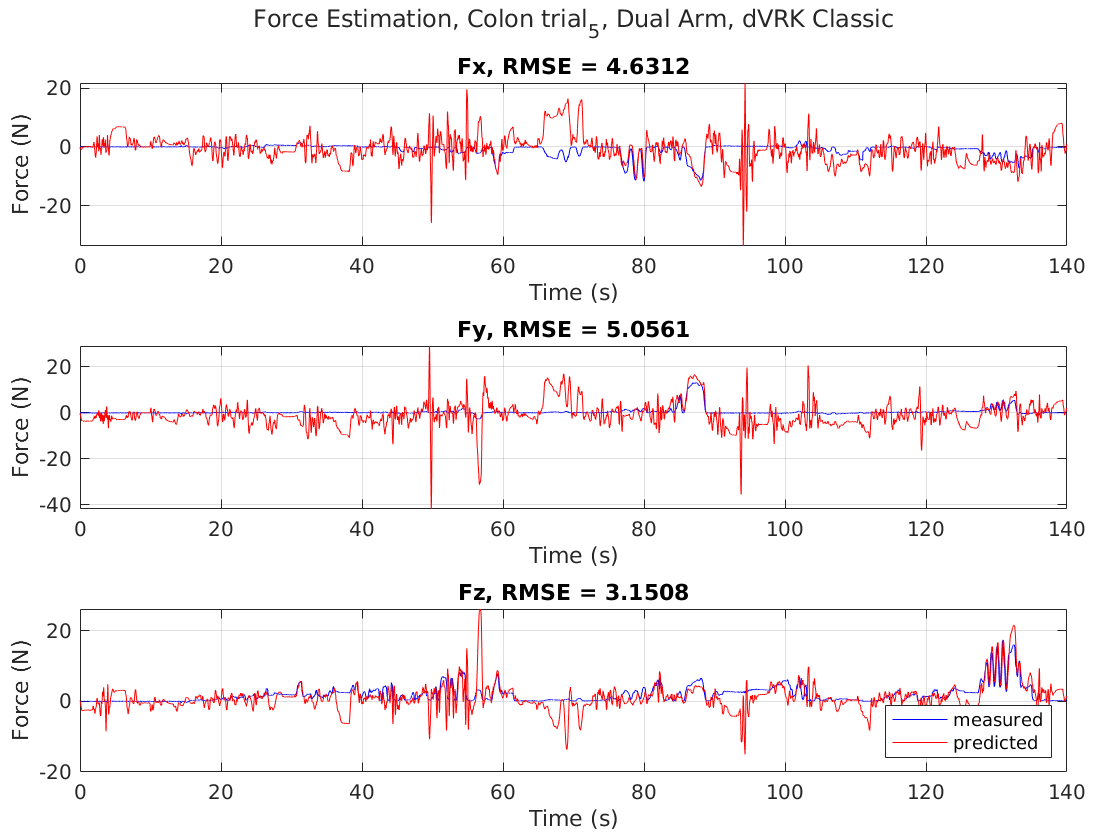


for i = 1:length(fs_pred_torque_2)
    fs_force_2(:,i) = inv(jacobian_2(:,:,i).') * (fs_diff_2(:,i));
    fs_force_2(1:3, i) = rotation2 * fs_force_2(1:3, i);
end

fs_force_2 = fs_force_2.';

fs_force_2 = fs_force_2(1:length(fs_force_1),:);
% real_force = real_force(1:length(fs_force_2),:);

windowSize = 30; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

fs_force_filt = filter(b,a,fs_force_1);

fs_force_unfilt = fs_force_1;

% fs_force = filter(b,a,fs_force);

loss_x_1 = mean(sqrt(mean( (fs_force_1(:,1) - real_force(:,1)).^2 )));
loss_y_1 = mean(sqrt(mean( (fs_force_1(:,2) - real_force(:,2)).^2 )));
loss_z_1 = mean(sqrt(mean( (fs_force_1(:,3) - real_force(:,3)).^2 )));
loss_taux_1 = mean(sqrt(mean( (fs_force_1(:,4) - real_force(:,4)).^2 )));
loss_tauy_1 = mean(sqrt(mean( (fs_force_1(:,5) - real_force(:,5)).^2 )));
loss_tauz_1 = mean(sqrt(mean( (fs_force_1(:,6) - real_force(:,6)).^2 )));

[minSix, maxSix] = bounds(fs_force_1(:,1));
boundX = abs(maxSix - minSix);
[minSiy, maxSiy] = bounds(fs_force_1(:,2));
boundY = abs(minSiy - maxSiy);
[minSiz, maxSiz] = bounds(fs_force_1(:,3));
boundZ = abs(maxSiz - minSiz);

loss_x_2 = mean(sqrt(mean( (fs_force_2(:,1) - real_force(:,1)).^2 )));
loss_y_2 = mean(sqrt(mean( (fs_force_2(:,2) - real_force(:,2)).^2 )));
loss_z_2 = mean(sqrt(mean( (fs_force_2(:,3) - real_force(:,3)).^2 )));
loss_taux_2 = mean(sqrt(mean( (fs_force_2(:,4) - real_force(:,4)).^2 )));
loss_tauy_2 = mean(sqrt(mean( (fs_force_2(:,5) - real_force(:,5)).^2 )));
loss_tauz_2 = mean(sqrt(mean( (fs_force_2(:,6) - real_force(:,6)).^2 )));

[minSix, maxSix] = bounds(fs_force_2(:,1));
boundX = abs(maxSix - minSix);
[minSiy, maxSiy] = bounds(fs_force_2(:,2));
boundY = abs(minSiy - maxSiy);
[minSiz, maxSiz] = bounds(fs_force_2(:,3));
boundZ = abs(maxSiz - minSiz);

figure()
tcl = tiledlayout(3,1, 'TileSpacing','Compact','Padding','Compact');

% title(tcl, sprintf('Force Estimation, LSTM, dual, %s, unfilt', test_folder))
title(tcl, sprintf('Force Estimation, Colon %s, Dual Arm, dVRK Classic', test_folder))





fs_force = fs_force_1 + fs_force_2;

plotLEN = 1:length(fs_force);

%%% slide window filt (left aligh)
windowSize = 50; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

fs_force_filt = filter(b,a,fs_force);

fs_force = fs_force_filt;

% %%% median filt
% for i=1:6
%     real_force_ft(:,i) = median(reshape(real_force(:,i), 100, length(real_force)/100));
%     fs_force_ft(:,i) = median(reshape(fs_force(:,i), 100, length(real_force)/100));
% end


loss_x = mean(sqrt(mean( (fs_force(:,1) - real_force(:,1)).^2 )));
loss_y = mean(sqrt(mean( (fs_force(:,2) - real_force(:,2)).^2 )));
loss_z = mean(sqrt(mean( (fs_force(:,3) - real_force(:,3)).^2 )));

loss_x_1 = mean(sqrt(mean( (fs_force_1(:,1) - real_force(:,1)).^2 )));
loss_y_1 = mean(sqrt(mean( (fs_force_1(:,2) - real_force(:,2)).^2 )));
loss_z_1 = mean(sqrt(mean( (fs_force_1(:,3) - real_force(:,3)).^2 )));

loss_x_2 = mean(sqrt(mean( (fs_force_2(:,1) - real_force(:,1)).^2 )));
loss_y_2 = mean(sqrt(mean( (fs_force_2(:,2) - real_force(:,2)).^2 )));
loss_z_2 = mean(sqrt(mean( (fs_force_2(:,3) - real_force(:,3)).^2 )));



nexttile
plot(joint_data_1(plotLEN), real_force(plotLEN,1), 'b')
hold on
title(sprintf('Fx, RMSE = %.4f', loss_x))
plot(joint_data_1(plotLEN), 1*(fs_force(plotLEN,1)), 'r')
xlabel('Time (s)')
ylabel('Force (N)')
grid on
hold off

nexttile
plot(joint_data_1(plotLEN), real_force(plotLEN,2), 'b')
hold on
title(sprintf('Fy, RMSE = %.4f', loss_y))
plot(joint_data_1(plotLEN), 1*(fs_force(plotLEN,2)), 'r')
xlabel('Time (s)')
ylabel('Force (N)')
grid on
hold off

nexttile
plot(joint_data_1(plotLEN), real_force(plotLEN,3), 'b')
hold on
title(sprintf('Fz, RMSE = %.4f', loss_z))
plot(joint_data_1(plotLEN), 1*(fs_force(plotLEN,3)), 'r')
xlabel('Time (s)')
ylabel('Force (N)')
grid on

legend('measured', 'predicted','Location', 'southeast')

hold off

% clf;
% 
% plot(0.005*(1:2000), real_force(8001:10000,3), 'b')
% hold on
% title(sprintf('Force Exerted during Colon Pulling, Measured vs. Estimated'))
% plot(0.005*(1:2000), 1*(fs_force_1(8001:10000,3) + fs_force_2(8001:10000,3)), 'r')
% xlabel('Time (s)')
% ylabel('Force (N)')
% fontsize(16,"points")
% grid on
% % pbaspect([6 1 1])
% 
% legend('measured', 'estimated')
% 
% hold off

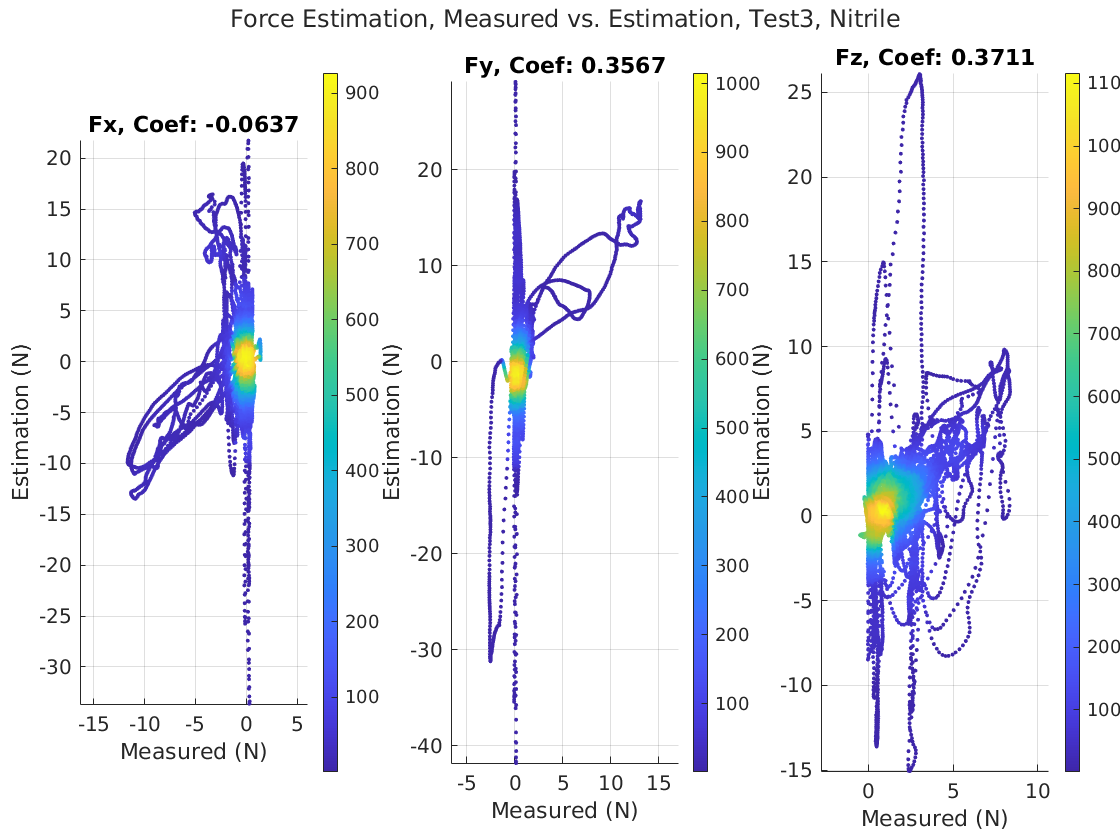

clf;
figure()
tcl1 = tiledlayout(1,3, 'TileSpacing','Compact','Padding','Compact');

title(tcl1, sprintf('Force Estimation, Measured vs. Estimation, Test3, Nitrile'));

plotLen = 1:19000;

nexttile
hold on
[RHO,PVAL] = corr(real_force(plotLen,1),fs_force(plotLen,1),'Type','Spearman');
    title(sprintf('Fx, Coef: %.4f', RHO))

grid on
axis equal
% xlim([0 8]);
% ylim([-6 11]);

data = [real_force(plotLen,1), 1*(fs_force(plotLen,1))];
radius = 1.5; 
density_2D = density2D_KD(data(:,1:2),radius); 
xq = min(data(:,1)):0.1:max(data(:,1));
p = polyfit(data(:,1),data(:,2),1);
x1 = linspace(min(data(:,1)),max(data(:,1)),100);
y1 = polyval(p,x1);
scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
colorbar

xlabel('Measured (N)')
ylabel('Estimation (N)')
axis equal

hold off

nexttile
hold on
[RHO,PVAL] = corr(real_force(plotLen,2),fs_force(plotLen,2),'Type','Spearman');
    title(sprintf('Fy, Coef: %.4f', RHO))

grid on
axis equal
% xlim([0 8]);
% ylim([-6 11]);

data = [real_force(plotLen,2), 1*(fs_force(plotLen,2))];
radius = 1.5; 
density_2D = density2D_KD(data(:,1:2),radius); 
xq = min(data(:,1)):0.1:max(data(:,1));
p = polyfit(data(:,1),data(:,2),1);
x1 = linspace(min(data(:,1)),max(data(:,1)),100);
y1 = polyval(p,x1);
scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
colorbar

xlabel('Measured (N)')
ylabel('Estimation (N)')
axis equal

hold off

nexttile
hold on
[RHO,PVAL] = corr(real_force(plotLen,3),fs_force(plotLen,3),'Type','Spearman');
    title(sprintf('Fz, Coef: %.4f', RHO))

grid on
axis equal
% xlim([0 8]);
% ylim([-6 11]);

data = [real_force(plotLen,3), 1*(fs_force(plotLen,3))];
radius = 1.5; 
density_2D = density2D_KD(data(:,1:2),radius); 
xq = min(data(:,1)):0.1:max(data(:,1));
p = polyfit(data(:,1),data(:,2),1);
x1 = linspace(min(data(:,1)),max(data(:,1)),100);
y1 = polyval(p,x1);
scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
colorbar

xlabel('Measured (N)')
ylabel('Estimation (N)')
axis equal

hold off




% clf;
% figure()
% tcl1 = tiledlayout(3,3, 'TileSpacing','Compact','Padding','Compact');
% 
% title(tcl1, sprintf('Force Estimation, Measured vs. Estimation, %s', test_folder));
% 
% 
% nexttile
% hold on
% title(sprintf('Fx, Dual Arm'))
% 
% data = [real_force(:,1), 1*(fs_force(:,1))];
% radius = 1.5; 
% density_2D = density2D_KD(data(:,1:2),radius); 
% xq = min(data(:,1)):0.1:max(data(:,1));
% p = polyfit(data(:,1),data(:,2),1);
% x1 = linspace(min(data(:,1)),max(data(:,1)),100);
% y1 = polyval(p,x1);
% scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
% colorbar
% plot(x1,y1,'LineStyle',':','LineWidth',2,'Color','r');
% 
% xlabel('Measured (N)')
% ylabel('Estimation (N)')
% axis equal
% grid on
% hold off
% 
% nexttile
% hold on
% title(sprintf('Fy, Dual Arm'))
% 
% data = [real_force(:,2), 1*(fs_force(:,2))];
% radius = 1.5; 
% density_2D = density2D_KD(data(:,1:2),radius); 
% xq = min(data(:,1)):0.1:max(data(:,1));
% p = polyfit(data(:,1),data(:,2),1);
% x1 = linspace(min(data(:,1)),max(data(:,1)),100);
% y1 = polyval(p,x1);
% scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
% colorbar
% plot(x1,y1,'LineStyle',':','LineWidth',2,'Color','r');
% 
% xlabel('Measured (N)')
% ylabel('Estimation (N)')
% axis equal
% grid on
% hold off
% 
% nexttile
% hold on
% title(sprintf('Fz, Dual Arm'))
% 
% data = [real_force(:,3), 1*(fs_force(:,3))];
% radius = 1.5; 
% density_2D = density2D_KD(data(:,1:2),radius); 
% xq = min(data(:,1)):0.1:max(data(:,1));
% p = polyfit(data(:,1),data(:,2),1);
% x1 = linspace(min(data(:,1)),max(data(:,1)),100);
% y1 = polyval(p,x1);
% scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
% colorbar
% plot(x1,y1,'LineStyle',':','LineWidth',2,'Color','r');
% 
% xlabel('Measured (N)')
% ylabel('Estimation (N)')
% axis equal
% grid on
% hold off
% 
% nexttile
% hold on
% title(sprintf('Fx, PSM1'))
% 
% data = [real_force(:,1), 1*(fs_force_1(:,1))];
% radius = 1.5; 
% density_2D = density2D_KD(data(:,1:2),radius); 
% xq = min(data(:,1)):0.1:max(data(:,1));
% p = polyfit(data(:,1),data(:,2),1);
% x1 = linspace(min(data(:,1)),max(data(:,1)),100);
% y1 = polyval(p,x1);
% scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
% colorbar
% plot(x1,y1,'LineStyle',':','LineWidth',2,'Color','r');
% 
% xlabel('Measured (N)')
% ylabel('Estimation (N)')
% axis equal
% grid on
% hold off
% 
% nexttile
% hold on
% title(sprintf('Fy, PSM1'))
% 
% data = [real_force(:,2), 1*(fs_force_1(:,2))];
% radius = 1.5; 
% density_2D = density2D_KD(data(:,1:2),radius); 
% xq = min(data(:,1)):0.1:max(data(:,1));
% p = polyfit(data(:,1),data(:,2),1);
% x1 = linspace(min(data(:,1)),max(data(:,1)),100);
% y1 = polyval(p,x1);
% scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
% colorbar
% plot(x1,y1,'LineStyle',':','LineWidth',2,'Color','r');
% 
% xlabel('Measured (N)')
% ylabel('Estimation (N)')
% axis equal
% grid on
% hold off
% 
% nexttile
% hold on
% title(sprintf('Fz, PSM1'))
% 
% data = [real_force(:,3), 1*(fs_force_1(:,3))];
% radius = 1.5; 
% density_2D = density2D_KD(data(:,1:2),radius); 
% xq = min(data(:,1)):0.1:max(data(:,1));
% p = polyfit(data(:,1),data(:,2),1);
% x1 = linspace(min(data(:,1)),max(data(:,1)),100);
% y1 = polyval(p,x1);
% scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
% colorbar
% plot(x1,y1,'LineStyle',':','LineWidth',2,'Color','r');
% 
% xlabel('Measured (N)')
% ylabel('Estimation (N)')
% axis equal
% grid on
% hold off
% 
% nexttile
% hold on
% title(sprintf('Fx, PSM3'))
% 
% data = [real_force(:,1), 1*(fs_force_2(:,1))];
% radius = 1.5; 
% density_2D = density2D_KD(data(:,1:2),radius); 
% xq = min(data(:,1)):0.1:max(data(:,1));
% p = polyfit(data(:,1),data(:,2),1);
% x1 = linspace(min(data(:,1)),max(data(:,1)),100);
% y1 = polyval(p,x1);
% scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
% colorbar
% plot(x1,y1,'LineStyle',':','LineWidth',2,'Color','r');
% 
% xlabel('Measured (N)')
% ylabel('Estimation (N)')
% axis equal
% grid on
% hold off
% 
% nexttile
% hold on
% title(sprintf('Fy, PSM3'))
% 
% data = [real_force(:,2), 1*(fs_force_2(:,2))];
% radius = 1.5; 
% density_2D = density2D_KD(data(:,1:2),radius); 
% xq = min(data(:,1)):0.1:max(data(:,1));
% p = polyfit(data(:,1),data(:,2),1);
% x1 = linspace(min(data(:,1)),max(data(:,1)),100);
% y1 = polyval(p,x1);
% scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
% colorbar
% plot(x1,y1,'LineStyle',':','LineWidth',2,'Color','r');
% 
% xlabel('Measured (N)')
% ylabel('Estimation (N)')
% axis equal
% grid on
% hold off
% 
% h = nexttile;
% hold on
% title(sprintf('Fz, PSM3'))
% 
% data = [real_force(:,3), 1*(fs_force_2(:,3))];
% radius = 1.5; 
% density_2D = density2D_KD(data(:,1:2),radius); 
% scatter(data(:,1), data(:,2), 5, density_2D, 'filled');
% colorbar
% h1 = lsline(h);
% h1.Color = 'r'; h1.LineWidth = 5;
% 
% xlabel('Measured (N)')
% ylabel('Estimation (N)')
% axis equal
% grid on
% hold off

function density_2D = density2D_KD(data,radius)
% function: use KD tree to extract scatter 2D density features
% input: data - original data(m*3)    
% output：planes - plane parameters through fitting
M = size(data,1);
density_2D = zeros(M,1);
idx = rangesearch(data(:,1:2),data(:,1:2),radius,'Distance','euclidean','NSMethod','kdtree');
for i = 1:M
    density_2D(i,1) = length(idx{i})/(pi*radius^2);
end
end

% nexttile
% plot(joint_data(1:length(fs_force)), real_force(:,4), 'b')
% hold on
% title(sprintf('Taux, RMSE = %.4f', loss_taux))
% plot(joint_data(1:length(fs_force)), fs_force(:,4), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% hold off
% 
% nexttile
% plot(joint_data(1:length(fs_force)), real_force(:,5), 'b')
% hold on
% title(sprintf('Tauy, RMSE = %.4f', loss_tauy))
% plot(joint_data(1:length(fs_force)), fs_force(:,5), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% hold off
% 
% nexttile
% plot(joint_data(1:length(fs_force)), real_force(:,6), 'b')
% hold on
% title(sprintf('Tauz, RMSE = %.4f', loss_tauz), 'Interpreter', 'tex')
% plot(joint_data(1:length(fs_force)), fs_force(:,6), 'r')
% xlabel('Time/s')
% ylabel('Torque/Nm')
% legend('measured', 'predicted')
% hold off








% 
% 
% 
% 
% nexttile
% plot(real_force(:,1), 'b')
% hold on
% title(sprintf('Fx, RMSE = %.4f', loss_x))
% plot(fs_force(:,1), 'r')
% hold off
% 
% nexttile
% plot(real_force(:,2), 'b')
% hold on
% title(sprintf('Fy, RMSE = %.4f', loss_y))
% plot(fs_force(:,2), 'r')
% hold off
% 
% nexttile
% plot(real_force(:,3), 'b')
% hold on
% title(sprintf('Fz, RMSE = %.4f', loss_z))
% plot(fs_force(:,3), 'r')
% hold off
% 




% clf;
% 
% tcl = tiledlayout(2,1,'TileSpacing','Compact','Padding','Compact');
% 
% title(tcl, sprintf('Estimated Force for Si Pre & Post Filtering, LSTM'))
% 
% loss_x_unfilt = mean(sqrt(mean( (fs_force_unfilt(:,1) - real_force(:,1)).^2 )));
% 
% nexttile
% plot(joint_data(1:length(real_force)), real_force(:,1), 'b')
% hold on
% title(sprintf('Fx-unfiltered, RMSE = %.4f', loss_x_unfilt))
% plot(joint_data(1:length(real_force)), fs_force_unfilt(:,1), 'r')
% xlabel('Time (s)')
% ylabel('Force (N)')
% legend('measured', 'predicted')
% grid on
% hold off
% 
% nexttile
% plot(joint_data(1:length(real_force)), real_force(:,1), 'b')
% hold on
% title(sprintf('Fx-filtered, RMSE = %.4f', loss_x))
% plot(joint_data(1:length(real_force)), fs_force_filt(:,1), 'r')
% 
% xlabel('Time (s)')
% ylabel('Force (N)')
% grid on
% hold off





% 
% nexttile
% plot(real_force(:,4), 'b')
% hold on
% title(sprintf('taux, RMSE = %.4f', loss_taux))
% plot(fs_force(:,4), 'r')
% hold off
% 
% nexttile
% plot(real_force(:,5), 'b')
% hold on
% title(sprintf('\tauy, RMSE = %.4f', loss_tauy))
% plot(-fs_force(:,5), 'r')
% hold off
% 
% nexttile
% plot(real_force(:,6), 'b')
% hold on
% title(sprintf('\tau z, RMSE = %.4f', loss_tauz), 'Interpreter', 'tex')
% plot(fs_force(:,6), 'r')
% legend('measured', 'predicted')
% hold off




% t = jacobian(1,:,:);


% jacobian = jacobian.numpy()
% force = torch.zeros((joints.shape[0], 6))
% for i in range(joints.shape[0]):
%     j = jacobian[i,:].reshape(6,6)
%     jacobian_inv_t = torch.from_numpy(np.linalg.inv(j).transpose())
%     force[i,:] = torch.matmul(jacobian_inv_t, joints[i,:])
% return force

